Загрузка данных

Статистика матчей сборных по футболу за 2018 год

Строки - команды-хозяева

Столбцы - 17 признаков (в файле categories)

load data
load categories
load match

Предварительный анализ изменчивости отдельных признаков

Видим, что нужно нормировать, так как дисперсия Passes существенно отличается от дисперсии остальных признаков

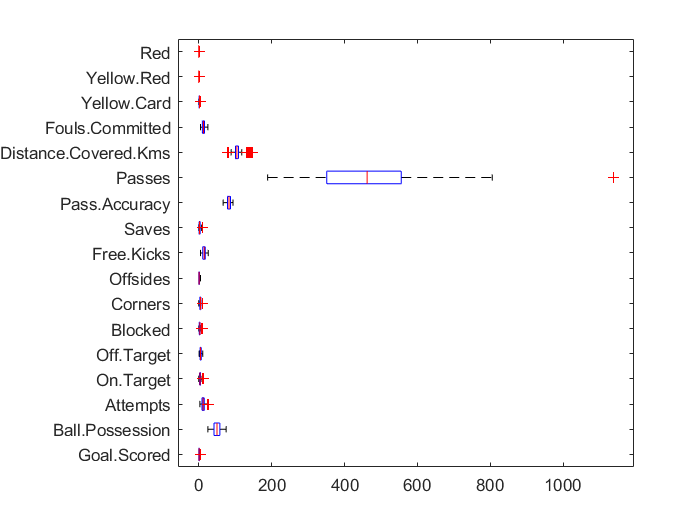

boxplot(data, 'orientation', 'horizontal', 'labels', names)

Нормировка

stdr = std(data);
sr = data./repmat(stdr, 128, 1);

График изменчивости отдельных признаков после нормировки

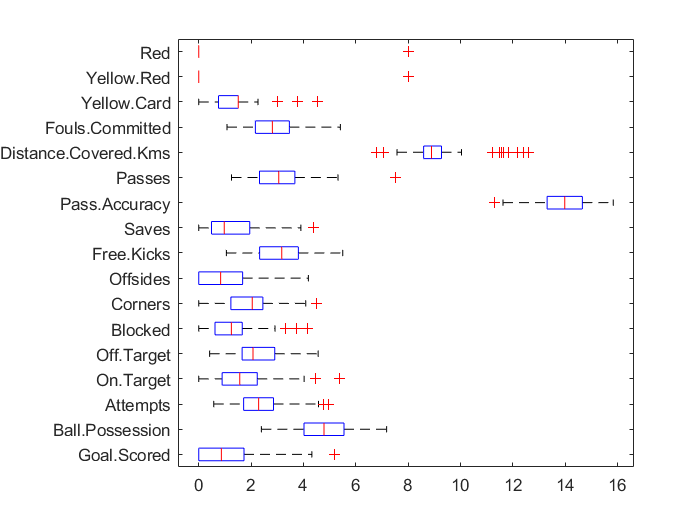

boxplot(sr, 'orientation', 'horizontal', 'labels', names);

Вычислим доли дисперсии, которые объясняются отдельными компонентами

[coefs, scores, variances, t2] = pca(sr);
percent_explained = 100 * variances / sum(variances)

percent_explained =    29.0314
    9.7712
    8.5823
    7.7563
    7.5289
    6.8278
    5.2837
    4.7494
    4.6397
    3.8793


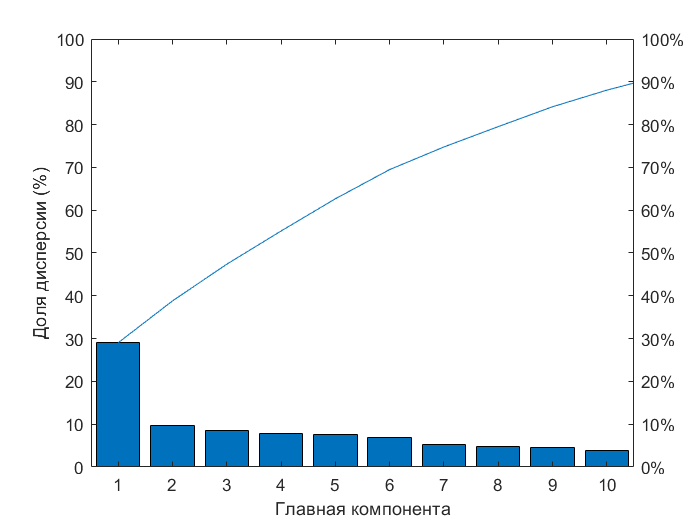

pareto(percent_explained)
xlabel('Главная компонента')
ylabel('Доля дисперсии (%)')

Из приведенного графика видно, что первые 3 главные компоненты объясняют порядка 53% общей дисперсии

Анализируя матрицу нагрузок для первых четырех компонент (поиск максимальных значений в строке), можно сказать, что:

**1. Первая главная компонента характеризует "Контроль игры" (определяется такими признаками как "Владение мячом", "Количество пассов", "Точность передач")**

**2.  Вторая главная компонента характеризует "Дисциплину" (определяется такими признаками как  "Фолы", "Желтые карточки")**

**3. Третья главная компонента характеризует "Атакующие действия" (определяется такими признаками как  "Забитые голы", "Количество атак")**

coefs(:, 1:3)

ans =     0.0670    0.1756    0.5882
    0.3712   -0.2391    0.0088
    0.3977    0.2605   -0.0649
    0.2804    0.2555    0.3389
    0.2688    0.3201   -0.1674
    0.3280    0.0137   -0.2801
    0.3363    0.1104   -0.1864
    0.0191   -0.2435    0.2734
    0.1068    0.0491    0.2639
   -0.1691   -0.0795   -0.3240


Совместный график данных и коэффициентов исходных признаков для первых трех главных компонент

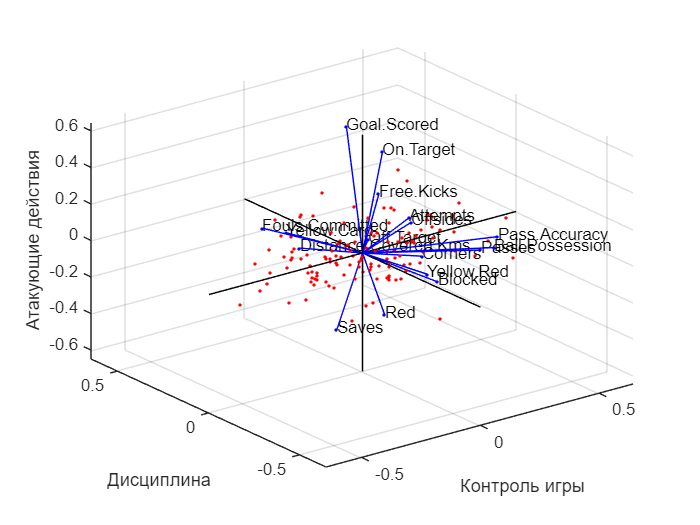

biplot(coefs(:,1:3),'scores',scores(:,1:3),'varlabels', names);
xlabel('Контроль игры')
ylabel('Дисциплина')
zlabel('Атакующие действия')